# Looking at resting state data sets 

Start with most recent one, see if it's DC coupled, and go from there


% set up the workspace


close all;clear all;clc

Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

subjid = input('What is the subject ID?  \n','s')

subjid = 78283a


load(fullfile(OUTPUT_DIR,'TDTtoMATfiles','78283a_RestingState','RestingState-2.mat'))




## Load in the relevant data of interest

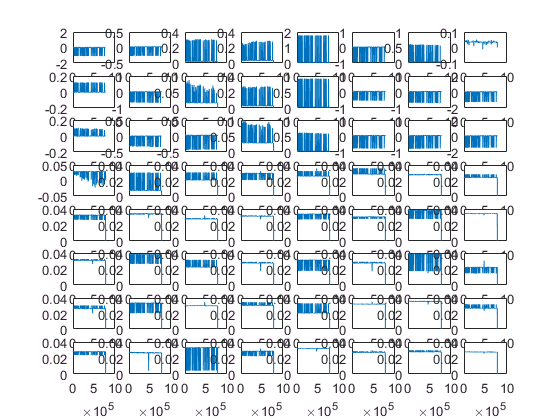

fs = Wave.info.SamplingRateHz;
ECoGData = Wave.data;


figure(1)
for i = 1:64
    subplot(8,8,i);
    plot(ECoGData(:,i));
end

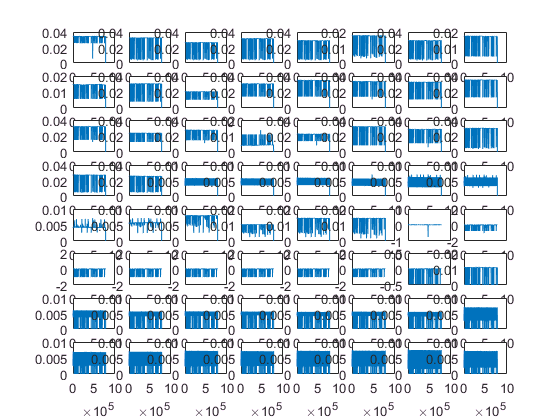

figure(2)
for i = 65:128
    subplot(8,8,i-64);
    plot(ECoGData(:,i));
end

## Load in the montage for plotting 

% make fake montage


%there appears to be no montage for this subject currently
Montage.Montage = 64;
Montage.MontageTokenized = {'Grid(1:64)'};
Montage.MontageString = Montage.MontageTokenized{:};
Montage.MontageTrodes = zeros(64, 3);
Montage.BadChannels = [];
Montage.Default = true;

% get electrode locations
locs = trodeLocsFromMontage(sid, Montage, false);

